# $\pi$ Estimate with Monte Carlo Method with Matlab:

*Jeremy Mackey*

One way to estimate $\pi$ is by a Monte Carlo method.

Knowing area of circle = $\pi r^2$

Given a circle $C$ with $r=0\ldotp 5$, enclosed by a (1x1) plot $P$

$C_{\mathrm{area}} =\frac{\pi }{4}$ and $P_{\mathrm{area}} ={\mathrm{width}}^2 ={\left(2r\right)}^2 =4r^2 =1$

So, the ratio of *circle* area to *plot* area is: $\frac{C_{\mathrm{area}} }{P_{\mathrm{area}} }=$$\frac{\left(\frac{\pi }{4}\right)}{1}=\frac{\pi }{4}$ 

By **randomly** sampling $n$ points on the plot $P$*, *we can get a rough approximation of $P_{\mathrm{area}}$ by counting the number of points in $P$.

We can also count the number of points that end up inside $C$, giving us an approximation of $C_{\mathrm{area}}$.

**Multiplying out **$4*\frac{\left(\mathrm{points}\;\mathrm{inside}\;C\right)}{\left(\mathrm{points}\;\mathrm{inside}\;P\right)}$ **can estimate **$\pi$. **Using the ratio of **$\frac{C_{\mathrm{area}} }{P_{\mathrm{area}} }$.

As $n$ increases so does out estimate of $\pi$. With higher $n$ values, our estimates of  $C_{\mathrm{area}}$ and $P_{\mathrm{area}}$ become more accurate. This is like increasing the resolution at which we measure $P\;\mathrm{and}\;C$. (more points can better capture their area). More accurate approximations of these area values leads to a more accurate approximation of $\pi$.

The results can be see in the **GIF** and **line plot** below:

% Gradual n at first
begSamples = (1:75:1000);
% Speed up sampling (make gif cooler)
moreSamples = (begSamples(end)+1000:1000:45000);
samples=[begSamples,moreSamples];

% Begin sampling --------------------------------
for i=1:length(samples)
curSample=samples(i);
x=rand(curSample,1);  % get random numbers to plot
y=rand(curSample,1);
distance=sqrt((x-0.5).^2+(y-0.5).^2);  % distance from center of circle

% Check if points in circle of radius=0.5
inRadius = distance<=0.5;
% Plot points, color indicates if in circle
plot(x(inRadius),y(inRadius),".b");
hold on;
plot(x(~inRadius),y(~inRadius),'.c');
axis square  % make it pretty

% Estimate pi    --------------------------------
% Pi = 4*(num points in circle)/(num points in P)
piEstimate(i)=4*sum(inRadius)/curSample;
% Update plot values
str1=sprintf('n = %d, %s = %.6f',curSample, '\pi',piEstimate(i));
title(str1,'FontName','Times New Roman');
drawnow;

% Save frames to make GIF
frame = getframe(gcf);
image{i} = frame2im(frame);
clf;
end
hold off;

% Make the GIF / Save to disk
filename = 'montecarlo.gif';
for i = 1:length(samples)
    [A1,map] = rgb2ind(image{i},256);
    if i == 1
        imwrite(A1,map,filename,'gif','LoopCount',Inf,'DelayTime',0.4);
    else
        imwrite(A1,map,filename,'gif','WriteMode','append','DelayTime',0.4);
    end
end

Here we can plot the absolute difference of $\pi$ and our estimate Vs. Sample size used:

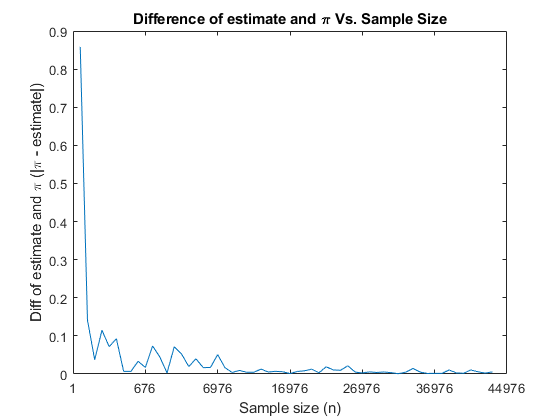

% Plot the difference between pi and estimate pi
diff = abs(pi - piEstimate);
plot(diff)
title('Difference of estimate and \pi Vs. Sample Size')
ylabel('Diff of estimate and \pi (|\pi - estimate|)')
xlabel('Sample size (n)')
xticklabels([samples(1) samples(10) samples(20) samples(30) samples(40) samples(50) samples(58)])
saveas(gcf, 'piDiffPlot.png')

As we can see increasing $n$ increases the accuracy of our $\pi$ estimation, as the line trends down over time. There are still fluctuations due to the random nature of the method, but overall it is trending closer to $\pi$.